# Example Path

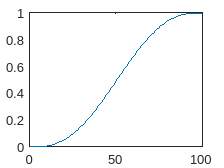

start = [0;0;0];
final = [1;1;1];
tf = 1;

xp = quintic(0, tf, [0; 0; 0; 1; 0; 0;]);
yp = quintic(0, tf, [0; 0; 0; 1; 0; 0;]);
zp = quintic(0, tf, [0; 0; 0; 1; 0; 0;]);
psip = quintic(0, tf, [0; 0; 0; pi; 0; 0;]);

plot(polyval(flipud(xp), 0:0.01:tf));


g = 9.81;
% parameterized straight line path with constant yaw
syms t
pos_path = [sym_poly(xp); sym_poly(yp); sym_poly(zp); sym_poly(psip)];
% pos_path = [(final-start)/time * t; 0]
% pos_path = [cos(t); cos(t); 4; cos(t)]; % more complicated example
vel_path = simplify(diff(pos_path, t))

$$vel\_path = \left(\begin{array}{c} 30\,t^{2}\,{\left(t-1\right)}^{2}\\ 30\,t^{2}\,{\left(t-1\right)}^{2}\\ 30\,t^{2}\,{\left(t-1\right)}^{2}\\ 30\,\pi \,t^{2}\,{\left(t-1\right)}^{2} \end{array}\right)$$

accel_path = simplify(diff(vel_path, t))

$$accel\_path = \left(\begin{array}{c} 60\,t\,\left(2\,t^{2}-3\,t+1\right)\\ 60\,t\,\left(2\,t^{2}-3\,t+1\right)\\ 60\,t\,\left(2\,t^{2}-3\,t+1\right)\\ 60\,\pi \,t\,\left(2\,t^{2}-3\,t+1\right) \end{array}\right)$$

## Calculate body frame from path

tee = accel_path(1:3) + [0;0;g]

$$tee = \left(\begin{array}{c} 60\,t\,\left(2\,t^{2}-3\,t+1\right)\\ 60\,t\,\left(2\,t^{2}-3\,t+1\right)\\ 60\,t\,\left(2\,t^{2}-3\,t+1\right)+\frac{981}{100} \end{array}\right)$$

xc = [cos(pos_path(4)), sin(pos_path(4)), 0]'

$$xc = \left(\begin{array}{c} \cos\left(6\,\pi \,{\left(\bar{t}\right)}^{5}-15\,\pi \,{\left(\bar{t}\right)}^{4}+10\,\pi \,{\left(\bar{t}\right)}^{3}\right)\\ \sin\left(6\,\pi \,{\left(\bar{t}\right)}^{5}-15\,\pi \,{\left(\bar{t}\right)}^{4}+10\,\pi \,{\left(\bar{t}\right)}^{3}\right)\\ 0 \end{array}\right)$$


zb = simplify(tee/norm(tee, 2));
yb = cross(zb, xc);
yb = simplify(yb/norm(yb,2));
xb = simplify(cross(yb, zb));

R_WB = [xb yb zb];

## Compute angular velocities

jerk_path = simplify(diff(accel_path, t));
syms m
u1 = m*norm(tee,2);
adot = jerk_path(1:3);
hw = m/u1 * (adot - dot(zb, adot)*zb)

$$hw = \begin{array}{l} \left(\begin{array}{c} \sigma_{1}\\ \sigma_{1}\\ -\frac{360\,t-360\,t^{2}+\frac{\left(\frac{\left(60\,\bar{t}\,\sigma_{3}+\frac{981}{100}\right)\,\left(360\,t^{2}-360\,t+60\right)}{\sigma_{2}}+\frac{120\,\bar{t}\,\sigma_{3}\,\left(360\,t^{2}-360\,t+60\right)}{\sigma_{2}}\right)\,\left(60\,t\,\sigma_{4}+\frac{981}{100}\right)}{\sigma_{2}}-60}{\sigma_{2}} \end{array}\right)\\ \mathrm{where}\\ \sigma_{1}=-\frac{360\,t-360\,t^{2}+\frac{60\,t\,\left(\frac{\left(60\,\bar{t}\,\sigma_{3}+\frac{981}{100}\right)\,\left(360\,t^{2}-360\,t+60\right)}{\sigma_{2}}+\frac{120\,\bar{t}\,\sigma_{3}\,\left(360\,t^{2}-360\,t+60\right)}{\sigma_{2}}\right)\,\sigma_{4}}{\sigma_{2}}-60}{\sigma_{2}}\\ \sigma_{2}=\sqrt{7200\,{\left|t\,\sigma_{4}\right|}^{2}+{\left|60\,t\,\sigma_{4}+\frac{981}{100}\right|}^{2}}\\ \sigma_{3}=2\,{\left(\bar{t}\right)}^{2}-3\,\bar{t}+1\\ \sigma_{4}=2\,t^{2}-3\,t+1 \end{array}$$


psidot = vel_path(4);
zw = [0;0;1];

p = dot(-hw, yb);
q = dot(hw, xb);
r = dot(psidot*zw, zb);
w = p*xb + q*yb + r*zb

## Compute Angular Accelerations

psidd = accel_path(4);
snap_path = simplify(diff(jerk_path));
addot = snap_path(1:3);
alpha_z = dot(psidd*zw, zb);

halpha = m/u1 * (addot - (dot(hw, adot)+dot(zb,addot))*zb - 2*dot(zb, adot)*hw);
alpha_y = dot(-halpha, yb);
alpha_x = dot(halpha, xb);

alpha = [alpha_x; alpha_y; alpha_z];

## Compute inputs from paper

syms ixx iyy izz
I = diag([ixx iyy izz]);
us_paper = I*alpha+cross(w, I*w);
u2 = us_paper(1);
u3 = us_paper(2);
u4 = us_paper(3);

u = [u1; u2; u3; u4]

## Compute torques (inputs for project)

l = 0.2; % [m]
sigma = 0.01;
A = [1 1 1 1;
     0 l 0 -l;
    -l 0 l 0;
    sigma -sigma sigma -sigma];
b = eval(subs(u, {'m', 'ixx', 'iyy', 'izz', 't'}, {0.5, 1.24, 1.24, 2.48, 0}))

b =     4.9050
 -138.2764
  138.2764
         0


## Actually Compute Torques

torques = linsolve(A,b)

torques =  -344.4648
 -344.4648
  346.9173
  346.9173
